Let's start by fixing the path

clear
clc

full_path='/storage/work/mjv5465/SAFE/';

restoredefaultpath;
addpath(genpath([full_path,'Data/']));
addpath(genpath([full_path,'Functions']));
addpath(genpath([full_path,'Scratch/']));
cd([full_path,'Scratch/']);

clear full_path  

## Anomaly decay results (McLean and Pontiff, 2016; Chen and Velikov, 2023)

The protocol for identifying new anomalies proposed by Novy-Marx and Velikov (2023) uses the anomalies from [Chen and Zimmerman's (2022)](https://cfr.pub/forthcoming/papers/chen2021open.pdf) [open source asset pricing library](https://www.openassetpricing.com/) for benchmarking. Thus, the Toolkit includes a function, getChenZimmermanAnomalies(), that downloads (if necessary) and reads in the 200+ anomalies from their google drive. The code snippet here replicates the anomaly decay results from [Chen and Velikov (2023)](https://nam10.safelinks.protection.outlook.com/?url=https%3A%2F%2Fwww.doi.org%2F10.1017%2FS0022109022000874&data=05%7C01%7Cvelikov%40psu.edu%7C3446a018a7474b2be8e708daee179df7%7C7cf48d453ddb4389a9c1c115526eb52e%7C0%7C0%7C638084082657141064%7CUnknown%7CTWFpbGZsb3d8eyJWIjoiMC4wLjAwMDAiLCJQIjoiV2luMzIiLCJBTiI6Ik1haWwiLCJXVCI6Mn0%3D%7C3000%7C%7C%7C&sdata=6yVIpbyBGL8DXfSrmD1tPGpm9taAk3T9Nxb2tWHgj7g%3D&reserved=0), which is just an extension of the main results in [McLean and Pontiff (2016)](https://onlinelibrary.wiley.com/doi/full/10.1111/jofi.12365).

clear
clc

% Time keeping
fprintf('Start at %s.\n',char(datetime('now')));

Start at 08-Jun-2024 06:59:27.



% Load a few variables
load dates
load ret
load tcosts
load NYSE
load prc
load exchcd
load me

% Read the Chen and Zimmerman anomalies
[anoms, labels, anomaly_summary] = getChenZimmermanAnomalies();

Done getting signals at at 08-Jun-2024 07:19:32.



% Store a few monthly indicators
mths = dates - 100*floor(dates/100);
JuneIndicator         = (mths==6);
JuneDecemberIndicator = (mths==6 | mths==12);
quarterEndIndicator   = (mths==3 | mths==6 | mths==9 | mths==12);

% Store some dimensions
[nMonths, nStocks, nAnoms] = size(anoms);

% Loop through the anomalies
for i=1:nAnoms
    
    % Store the current anomaly
    var = anoms(:,:,i);
        
    % Finds the row in the summary file
    r = find(strcmp(anomaly_summary.Acronym, labels(i)));
    
    % Figure out the rebalancing period
    if anomaly_summary.PortfolioPeriod(r) == 12 || ...
       anomaly_summary.PortfolioPeriod(r) == 36
        var(~JuneIndicator,:) = nan;
    elseif anomaly_summary.PortfolioPeriod(r) == 6
        var(~JuneDecemberIndicator,:) = nan;
    elseif anomaly_summary.PortfolioPeriod(r) == 3
        var(~quarterEndIndicator,:) = nan;
    end
        
    % Check for potential filters
    if ~strcmp(anomaly_summary.Filter(r), '')
        filterString = regexprep(anomaly_summary.Filter(r), ' ', '');
        if contains(filterString, 'abs(prc)>1')
            var(abs(prc)<=1) = nan;  
        end
        if contains(filterString, 'abs(prc)>5')
            var(abs(prc)<=5) = nan;  
        end
        if contains(filterString, 'exchcd%in%c(1,2)')
            var(exchcd>2) = nan;
        end
        if contains(filterString, 'exchcd==1')
            var(exchcd>1) = nan;
        end
        if contains(filterString, 'me>me_nyse20')
            indME5 = makeUnivSortInd(me, 5, NYSE);
            var(indME5==1) = nan;
        end
    end
                        
    % Determine the sample
    if isnan(anomaly_summary.StartMonth(r))
        sampleStart = 100*anomaly_summary.SampleStartYear(r) + 6;    
    else
        sampleStart = 100*anomaly_summary.SampleStartYear(r) + anomaly_summary.StartMonth(r);
    end
    lastHoldDate = find(sum(isfinite(var),2)>0,1,'last') + anomaly_summary.PortfolioPeriod(r);
    sampleEnd = dates(min(lastHoldDate, nMonths));
    dts = [sampleStart sampleEnd];
    
    % Determine the number of portfolios
    if strcmp(anomaly_summary.Acronym(r), 'ChangeInRecommendation')
        bpts = prctile(var,[20 80],2);        
        ind = 1 * (var<=repmat(bpts(:,1), 1, nStocks)) + ...
              2 * (var>=repmat(bpts(:,2), 1, nStocks));        
    elseif ismember(anomaly_summary.Acronym(r), {'NumEarnIncrease','RDcap'})
        ind = 1 * (var==0) + ...
              2 * (var>0);
    elseif strcmp(anomaly_summary.Cat_Form(r), 'discrete')       
        uVals = unique(var);
        uVals(isnan(uVals)) = [];
        ind = 1 * (var==min(uVals)) + ...
              2 * (var==max(uVals));
    else
        if isnan(anomaly_summary.LSQuantile(r))
            nptfs = 5;
        else
            nptfs = round(1/anomaly_summary.LSQuantile(r));
        end
        ind = makeUnivSortInd(var,nptfs);  
        if strcmp(anomaly_summary.QuantileFilter(r),'NYSE')
            ind = makeUnivSortInd(var,nptfs,NYSE);  
        end
        ind = 1 * (ind==1) + ...
              2 * (ind==nptfs);
    end

    % Run the univariate regression
    if strcmp(anomaly_summary.StockWeight(i), 'VW')
        res(i,1) = runUnivSort(ret, ind, dates, me, 'weighting', 'v', ...
                                                    'timePeriod', dts, ...
                                                    'plotFigure', 0, ...
                                                    'printResults', 0);  
    else
        res(i,1) = runUnivSort(ret, ind, dates, me, 'weighting', 'e', ...
                                                    'timePeriod', dts, ...
                                                    'plotFigure', 0, ...
                                                    'printResults', 0);      
    end
end

% Timekeeping
fprintf('Done running sorts at at %s.\n', char(datetime('now')));

Done running sorts at at 08-Jun-2024 07:23:13.


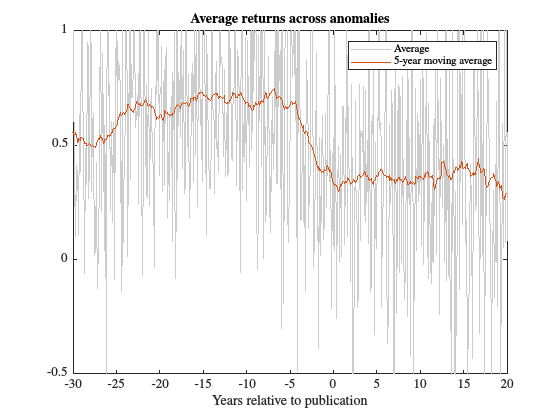

% Make anomaly returns relative to publication
relativeRets    = nan(2*nMonths+1, nAnoms);

% Loop through the anomalies
for i=1:nAnoms
    % Find the row for this anomaly in the summary table
    r = find(strcmp(anomaly_summary.Acronym,labels(i)));

    % Store the publication date (assume December)
    pubDate = 100*anomaly_summary.Year(r) + 12;

    % Find the publication date in the univariate sort structure
    e = find(res(i).dates==pubDate);

    % Store the returns in the relative returns matrix
    prePubInd = nMonths-e+1:nMonths;
    relativeRets(prePubInd,i) = res(i).pret(1:e,end);
    
    postPubInd = (nMonths+1):(nMonths+length(res(i).dates)-e);
    relativeRets(postPubInd,i) = res(i).pret(e+1:end,end);    
end

% Now let's plot the figure
figure;
x = (-nMonths:nMonths)/12;
y = 100 * mean(relativeRets, 2, 'omitnan');
plot(x, y, 'Color', [0.8 0.8 0.8]);
hold on;
smoothY = 100 * moving(mean(relativeRets, 2, 'omitnan'), 60);
plot(x, smoothY);
ylim([-0.5 1]);
xlim([-30 20]);
xlabel('Years relative to publication');
title('Average returns across anomalies');
legend('Average','5-year moving average');

## Combining anomalies:

Let's read in and fill in the 23 anomalies from Novy-Marx and Velikov (2016):

clear
clc

load dates
load me
load ret
load NYSE
load tcosts
load ff

% Read the signals data
[anoms23, labels23] = getAnomalySignals('novyMarxVelikovAnomalies.csv', 1, 2);
nAnoms = size(anoms23, 3);
nStocks = size(ret, 2);

% Fill those in
filledAnoms = nan(size(anoms23));
for i = 1:nAnoms
    % Fill the months for the annual ones
    var = FillMonths(anoms23(:, :, i));
    
    % Create a monthly rank and standardize to be between -0.5 and 0.5
    var = tiedrank(var')';
    var = (var - 1) ./ (max(var, [], 2)-1);
    var = var - 0.5;        
    
    % Fill the observations with market with the median for this
    % characteristic (i.e., 0)
    indToZero = isnan(var) & isfinite(me);    
    var(indToZero) = 0;
    
    % Set to NaN all observations where we don't have a market cap
    var(isnan(me)) = nan;
    
    % Assign to the new 3-d array
    filledAnoms(:, :, i) = var;      
end

Let's start with just combining the ranks:

%% Average rank
eret = sum(filledAnoms,3);
eret(isnan(me)) = nan;


ind = makeUnivSortInd(eret, 10, NYSE);
res = runUnivSort(ret, ind, dates, me, 'factorModel', 6);

     ---------------------------------------------------------------------------- 
              Value-weighted portfolio sort, 1-month holding period
              Excess returns, alphas, and loadings on:
              Fama and French 6-factor model
     ---------------------------------------------------------------------------- 
                    xret    alpha      mkt      smb      hml      rmw      cma      umd
                                                                                         
               1   -0.189   -0.527    1.060    0.264   -0.237   -0.311   -0.168    -0.432
                  [-0.92]  [-7.91]  [66.52]  [11.47]  [-7.76]  [-9.98]  [-3.75]  [-27.38]
                                                                                         
               2    0.204   -0.353    1.028    0.070   -0.035   -0.092   -0.128    -0.208
                  [ 1.15]  [-6.10]  [74.28]  [ 3.49]  [-1.32]  [-3.41]  [-3.27]  [-15.18]
                                      

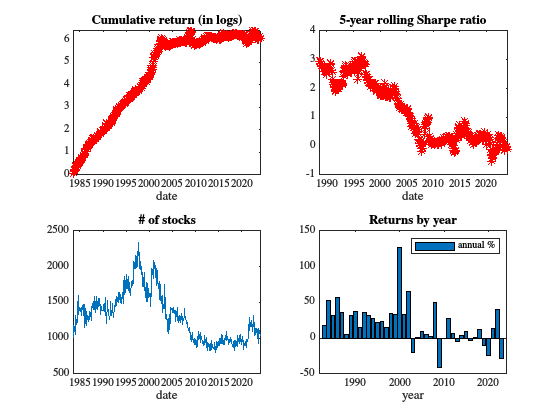

     ---------------------------------------------------------------------------- 
              Value-weighted portfolio sort, 1-month holding period
              Excess returns, alphas, and loadings on:
              Fama and French 6-factor model
     ---------------------------------------------------------------------------- 
                    xret    alpha      mkt      smb      hml      rmw      cma      umd
                                                                                         
               1   -0.099   -0.423    1.054    0.309   -0.211   -0.343   -0.154    -0.432
                  [-0.33]  [-4.86]  [50.80]  [ 9.79]  [-5.61]  [-8.62]  [-2.77]  [-21.91]
                                                                                         
               2    0.218   -0.352    1.041    0.113   -0.000   -0.096   -0.123    -0.196
                  [ 0.88]  [-4.73]  [58.71]  [ 4.18]  [-0.00]  [-2.82]  [-2.58]  [-11.61]
                                      

ind = makeUnivSortInd(eret, 10, NYSE);
res = runUnivSort(ret, ind, dates, me, 'factorModel', 6, ...
                                       'timePeriod', 198306);

save Data/eret_rank eret

Let's look at a combined rank based on Fama-MacBeths:

% Find the start date
s = find(dates==197306);

% Store the number of months
nMonths = length(dates);

% Determine the rolling period
T = 120;

% Initialize the expected return matrix
eret = nan(size(me));

% We'll do that in parallel using parfor
tic;
parfor i=(s+T+1):nMonths
    % Timekeeping
    if mod(i,120)==0
        fprintf('Done until %d @ %s.\n',dates(i),char(datetime('now')));
    end
    
    % Store this rolling period of T months
    rollPeriodChars = filledAnoms(i-T+1:i, :, :);
    
    % Reshape 
    fmbX = reshape(rollPeriodChars, T, nStocks * nAnoms);
    fmbY = 100*ret(i-T+1:i, :);
    
    % Run the Fama-MacBeth
    res = runFamaMacBeth(fmbY, fmbX, dates(i-T+1:i), 'printResults', 0);

    % Calculate the fitted values & store in eret
    X = permute(filledAnoms(i,:,:), [2 3 1]);
    bhat = res.bhat(2:end)';
    eret(i,:) = [X * bhat]';
end

Starting parallel pool (parpool) using the 'Processes' profile ...
Connected to parallel pool with 20 workers.
Done until 198511 @ 08-Jun-2024 07:27:04.
Done until 199511 @ 08-Jun-2024 07:27:20.
Done until 200511 @ 08-Jun-2024 07:29:03.
Done until 201511 @ 08-Jun-2024 07:29:18.


toc;

Elapsed time is 238.301822 seconds.


     ---------------------------------------------------------------------------- 
              Value-weighted portfolio sort, 1-month holding period
              Excess returns, alphas, and loadings on:
              Fama and French 6-factor model
     ---------------------------------------------------------------------------- 
                    xret    alpha      mkt      smb      hml      rmw      cma      umd
                                                                                         
               1   -0.030   -0.484    1.085    0.274   -0.106   -0.332   -0.146    -0.275
                  [-0.10]  [-4.39]  [41.34]  [ 6.88]  [-2.22]  [-6.61]  [-2.08]  [-11.02]
                                                                                         
               2    0.481   -0.088    0.992    0.142   -0.009   -0.115   -0.097   -0.135 
                  [ 2.03]  [-1.07]  [50.55]  [ 4.76]  [-0.25]  [-3.05]  [-1.85]  [-7.26] 
                                      

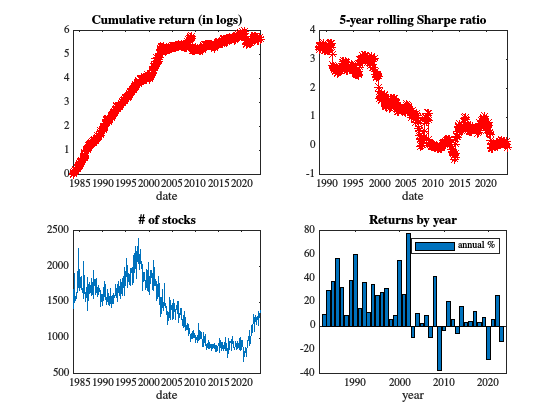

ind = makeUnivSortInd(eret, 10, NYSE);
res = runUnivSort(ret, ind, dates, me, 'factorModel', 6);

save Data/eret_fmb eret

Let's do Partial Least Squares from Light, Maslov, and Rytchkov (2017)

     ---------------------------------------------------------------------------- 
              Value-weighted portfolio sort, 1-month holding period
              Excess returns, alphas, and loadings on:
              Fama and French 6-factor model
     ---------------------------------------------------------------------------- 
                    xret    alpha      mkt      smb      hml      rmw      cma      umd
                                                                                        
               1    0.001   -0.459    1.154    0.386   -0.023   -0.282   -0.309   -0.305
                  [ 0.00]  [-2.78]  [30.30]  [ 6.70]  [-0.32]  [-3.78]  [-2.80]  [-8.07]
                                                                                        
               2    0.337   -0.178    1.054    0.207    0.020   -0.066   -0.251   -0.193
                  [ 1.36]  [-1.57]  [40.43]  [ 5.26]  [ 0.40]  [-1.30]  [-3.31]  [-7.46]
                                            

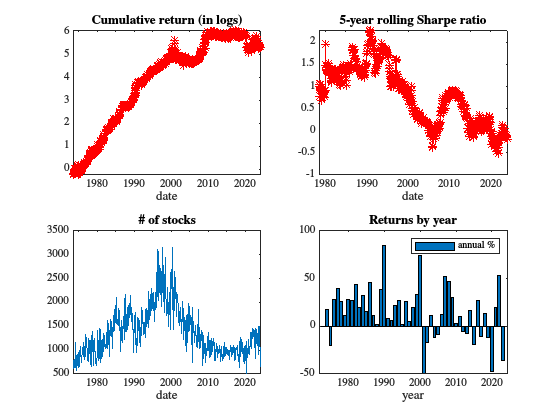

% Initialize the expected return matrix & lambda matrices
eret = nan(size(ret));
lambda = nan(nMonths, nAnoms);

% Loop over the months
for i = s:nMonths
    % Store the returns & characteristics
    y = ret(i,:)';
    x = permute(filledAnoms(i-1, :, :), [2 3 1]);
    xt = permute(filledAnoms(i, :, :), [2 3 1]);
    
    % Step 1
    const = ones(nStocks, 1);
    for j = 1:nAnoms
        res = nanols(y, x(:, j));
        lambda(i,j) = res.beta;
    end
    
    % Step 2
    const = ones(nAnoms, 1);
    for j = 1:nStocks
        res = nanols(xt(j,:)', lambda(i, :)');
        eret(i, j) = res.beta;
    end
end
   
% Check the predictability
ind = makeUnivSortInd(eret, 10, NYSE);
res = runUnivSort(ret, ind, dates, me, 'factorModel', 6);

save Data/eret_pls eret

Next, let's use Kelly, Priutt, and Su's (2019) IPCA. The code here is a version of their posted code for the paper. It uses their num_IPCA_estimate_ALS().m function, which is stored in the /Function/Assay functions/ directory of the Assaying Anomalies package.

clear chars

% Store excess returns & transpose(!)
xret = (ret - repmat(rf, 1, nStocks))';

% Lag the characteristics
for i = 1:nAnoms
    chars(:, :, i) = lag(filledAnoms(:, :, i), 1, nan);
end

% Permute them & check for missing observations
chars = permute(chars,[2 1 3]);
LOC = ~isnan(chars);
LOC = all(LOC, 3) & ~isnan(xret);

% Find the s tart date
s = find(dates == 197306);

% Filter
LOC   = LOC(:, s:end);
chars = chars(:, s:end,:);
xret  = xret(:, s:end);
tdates = dates(s:end);


% Add a constant characteristic
chars(:, :, nAnoms+1)  = 1;

% Store a few constants
[~, T, L]         = size(chars);
Nts = sum(LOC);

% Construct X, W, X
chars = permute(chars, [1 3 2]); % chars is now NxLxT
Z     = chars;
bigW  = nan(L, L, T);
bigX  = nan(L, T);
for t = 1:T % parfor makes it too big
    
    % W = Z'Z
    bigW(:,:,t) = (1/Nts(t)) * Z(LOC(:,t),:,t)' * Z(LOC(:,t),:,t); 
    
    % X = Z'r
    bigX(:,t)   = (1/Nts(t)) * Z(LOC(:,t),:,t)' * xret(LOC(:,t),t); 
end

% Store some optimization parameteres
K = 5;
als_opt.MaxIterations = 10000;
als_opt.Tolerance     = 1e-6;
bigNts = sum(LOC);

% Store a couple of constants
[N, ~, T] = size(Z);

% Initialize a temporary expected return matrix
temp_eret = nan(T, nStocks);

% Loop over the months
for t=120:T-1
    % Timekeeping
    if mod(t,120)==0
        fprintf('Done with first until %d @ %s.\n',tdates(t),char(datetime('now')));
    end
    X   = bigX(:, t-119:t);    % this is X known through t
    W   = bigW(:, :, t-119:t); % this is W known through t
    Nts = bigNts(t-119:t);     % this is Nts known through t
    
    % Start with initial Gamma and Beta
    [GammaBeta_initial, s, v] = svds(X, K);
    if t==120
        GB_Old      = GammaBeta_initial;
        F_Old       = s*v'; %ones(K,T);%
    else
        GB_Old      = GB_New;
        F_Old       = [F_New(:,2:end) s*v(end,:)'];
    end
    
    % Iterate until you reach tolerance or max iterations
    tol         = 1;
    iter        = 0;
    while iter <= als_opt.MaxIterations && tol > als_opt.Tolerance
        % Estimate
        [GB_New, F_New] = num_IPCA_estimate_ALS(GB_Old, W, X, Nts);

        % Store
        tol     = max([ abs(GB_New(:) - GB_Old(:)); abs(F_New(:)-F_Old(:)) ]);
        F_Old   = F_New;
        GB_Old  = GB_New;
        iter    = iter+1;
    end

    % Store
    GammaBeta = GB_New;
    Lambda = mean(F_New,2);        
    
    % Calculate the expected return
    temp_eret(t, :) = (Z(:,:,t+1) * GammaBeta * Lambda)';    
end

Done with first until 198305 @ 08-Jun-2024 07:35:44.
Done with first until 199305 @ 08-Jun-2024 07:36:26.
Done with first until 200305 @ 08-Jun-2024 07:36:52.
Done with first until 201305 @ 08-Jun-2024 07:37:16.
Done with first until 202305 @ 08-Jun-2024 07:37:59.


     ---------------------------------------------------------------------------- 
              Value-weighted portfolio sort, 1-month holding period
              Excess returns, alphas, and loadings on:
              Fama and French 6-factor model
     ---------------------------------------------------------------------------- 
                    xret    alpha      mkt      smb      hml      rmw      cma      umd
                                                                                         
               1    0.034   -0.380    1.068    0.334   -0.125   -0.290   -0.215    -0.320
                  [ 0.11]  [-3.14]  [36.95]  [ 7.62]  [-2.38]  [-5.25]  [-2.77]  [-11.63]
                                                                                         
               2    0.395   -0.163    0.999    0.139   -0.008   -0.086   -0.138   -0.163 
                  [ 1.64]  [-1.95]  [50.09]  [ 4.59]  [-0.22]  [-2.27]  [-2.58]  [-8.61] 
                                      

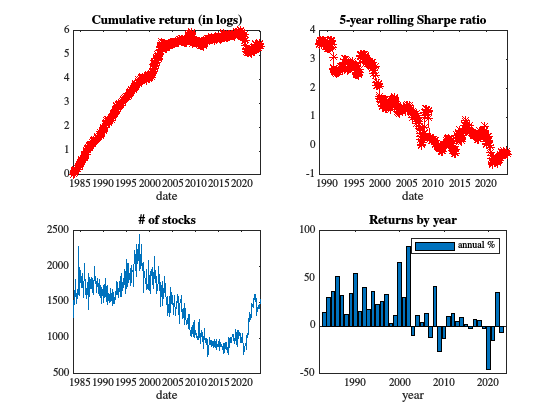

% Assign temp_eret to eret
s = find(dates == 197306);
eret = nan(size(ret));
eret(s:end, :) = temp_eret;

% Run the univariate sort
ind = makeUnivSortInd(eret, 10, NYSE);
res = runUnivSort(ret, ind, dates, me, 'factorModel', 6);

save Data/eret_ipca eret

Let's do LASSO next:

% Store a few constants
T = 120;
s = find(dates==197306);
nAnoms = size(filledAnoms, 3);
nMonths = length(dates);
nStocks = size(ret, 2);
nObs = nMonths * nStocks;

% Permute the characteristics
chars = permute(filledAnoms, [2 1 3]);

% Prepare the matrices for the LASSO estimation
lassoY = reshape(ret, nObs, 1);
lassoX = [];

% Lag & reshape the characteristics
for i = 1:nAnoms
    temp = lag(chars(:, :, i)', 1, nan);
    lassoX = [lassoX reshape(temp, nObs, 1)];
end

% Reshape the dates too
lassoDates = reshape(repmat(dates, 1, nStocks), nObs, 1);

% Filter
ind = isfinite(sum([lassoY lassoX], 2));
lassoY = lassoY(ind, :);
lassoX = lassoX(ind, :);
lassoDates = lassoDates(ind, :);

% Initialize an estimate the betas and expected returns
bhat = nan(nMonths, nAnoms);
eret = nan(size(me));

% We'll parallelize here
tic;
parfor i = (s+T):nMonths
    % Timekeeping
    if mod(i,120) == 0
        fprintf('Done until %d @ %s.\n', dates(i), char(datetime('now')));
    end
    
    % Find the past T months
    ind = lassoDates <= dates(i) & ...
          lassoDates >= dates(i-T+1);
    y = lassoY(ind);
    x = lassoX(ind,:);

    % Estimate LASSO with 5-fold cross-validation
    [B, fitInfo] = lasso(x, y, 'CV', 5);
    
    % Find the minimum MSE
    minMSE = find(fitInfo.MSE == min(fitInfo.MSE));
    
    % Assign to eret and bhat
    eret(i, :) = [permute(chars(:, i, :), [1 3 2]) * B(:, minMSE)]';
    bhat(i, :) = B(:,minMSE)';        
end

Done until 198511 @ 08-Jun-2024 07:38:30.
Done until 199511 @ 08-Jun-2024 07:38:37.
Done until 201511 @ 08-Jun-2024 07:39:49.
Done until 200511 @ 08-Jun-2024 07:39:40.


toc;

Elapsed time is 91.008418 seconds.


     ---------------------------------------------------------------------------- 
              Value-weighted portfolio sort, 1-month holding period
              Excess returns, alphas, and loadings on:
              Fama and French 6-factor model
     ---------------------------------------------------------------------------- 
                    xret    alpha      mkt      smb      hml      rmw      cma      umd
                                                                                         
               1    0.002   -0.419    1.062    0.229   -0.050   -0.285   -0.290    -0.276
                  [ 0.01]  [-4.35]  [46.16]  [ 6.54]  [-1.19]  [-6.47]  [-4.70]  [-12.63]
                                                                                         
               2    0.343   -0.306    1.060    0.171    0.028   -0.102   -0.059   -0.093 
                  [ 1.40]  [-3.75]  [54.57]  [ 5.80]  [ 0.80]  [-2.73]  [-1.14]  [-5.03] 
                                      

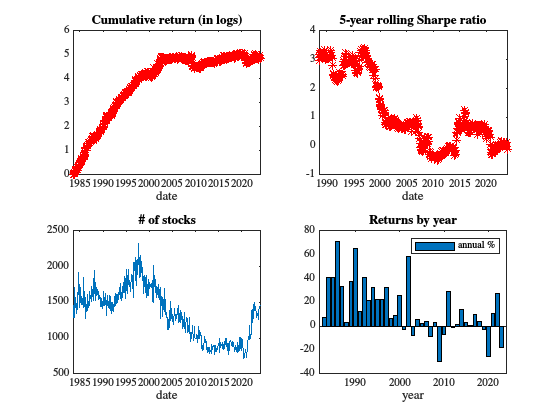

ind = makeUnivSortInd(eret, 10, NYSE);
res = runUnivSort(ret, ind, dates, me, 'factorModel', 6);

save Data/eret_lasso eret

 Now let's compare their performance:

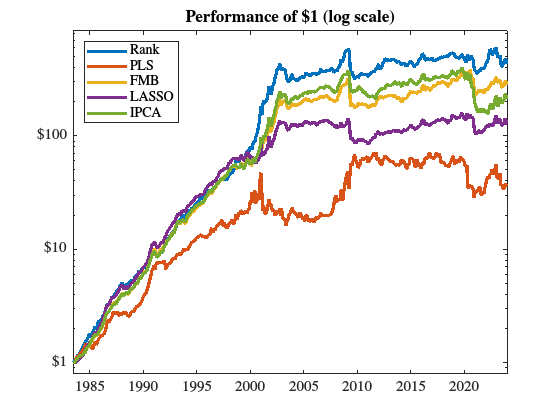

clear
clc

load ret
load dates
load me
load NYSE
load tcosts

eret_rank  = load('eret_rank.mat');
eret_fmb   = load('eret_fmb.mat');
eret_pls   = load('eret_pls.mat');
eret_lasso = load('eret_lasso.mat');
eret_ipca  = load('eret_ipca.mat');

ind = makeUnivSortInd(eret_rank.eret, 10, NYSE);
res_rank = runUnivSort(ret, ind, dates, me, 'timePeriod', 198306, ...
                                            'printResults', 0, ...
                                            'plotFigure', 0, ...
                                            'tcosts', tcosts);

ind = makeUnivSortInd(eret_fmb.eret, 10, NYSE);
res_fmb = runUnivSort(ret, ind, dates, me, 'timePeriod', 198306, ...
                                            'printResults', 0, ...
                                            'plotFigure', 0, ...
                                            'tcosts', tcosts);

ind = makeUnivSortInd(eret_pls.eret, 10, NYSE);
res_pls = runUnivSort(ret, ind, dates, me, 'timePeriod', 198306, ...
                                            'printResults', 0, ...
                                            'plotFigure', 0, ...
                                            'tcosts', tcosts);


ind = makeUnivSortInd(eret_lasso.eret, 10, NYSE);
res_lasso = runUnivSort(ret, ind, dates, me, 'timePeriod', 198306, ...
                                            'printResults', 0, ...
                                            'plotFigure', 0, ...
                                            'tcosts', tcosts);

ind = makeUnivSortInd(eret_ipca.eret, 10, NYSE);
res_ipca = runUnivSort(ret, ind, dates, me, 'timePeriod', 198306, ...
                                            'printResults', 0, ...
                                            'plotFigure', 0, ...
                                            'tcosts', tcosts);


% Plot the gross returns
grossret = [res_rank.pret(:, end) res_pls.pret(:, end) res_fmb.pret(:, end) res_lasso.pret(:, end) res_ipca.pret(:, end)];
figure;
ibbots(grossret, res_rank.dates, 'legendLabels', {'Rank','PLS','FMB','LASSO','IPCA'});

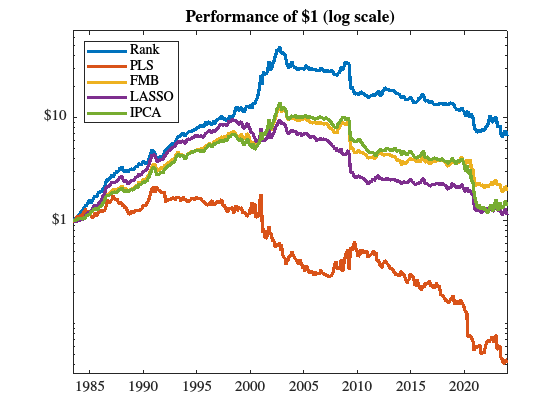

% Net returns
netret = [res_rank.netpret(:, end) res_pls.netpret(:, end) res_fmb.netpret(:, end) res_lasso.netpret(:, end) res_ipca.netpret(:, end)];
figure;
ibbots(netret, res_rank.dates, 'legendLabels', {'Rank','PLS','FMB','LASSO','IPCA'});

What happens to profits post 2000? Decimalization? Access to internet? High-frequency trading? Chordia, Subrahmanyam, and Tong (JAE, 2014) find similar results for individual anomalies.

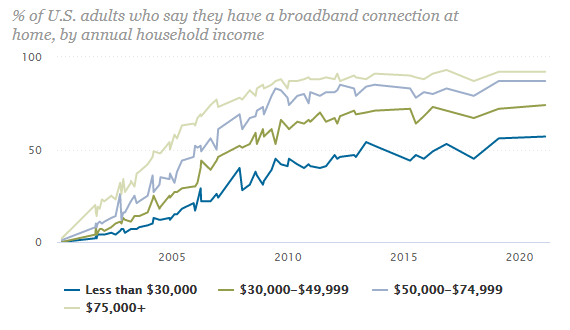

One of our results in Chen and Velikov (JFQA, 2023):